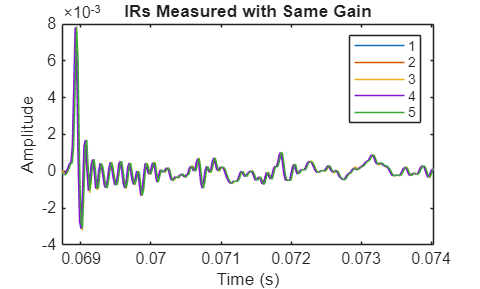

same_irs = irdata_100519;


num_irs = height(same_irs);
ir_len = 256;
start = 3300;
irs = zeros(num_irs, ir_len);

for i = 1:num_irs
    ir = same_irs{i, 2}.Amplitude(start:start+ir_len - 1).';
    irs(i, :) = ir;
end

t = same_irs{1, 2}.Time(start:start+ir_len - 1).';
figure
for i = 1:num_irs
    plot(t, irs(i, :), 'DisplayName', string(i));
    hold on;
end
hold off;
xlim([t(1), t(end)]);
legend();
title('IRs Measured with Same Gain')
xlabel('Time (s)')
ylabel('Amplitude')

latency_irs = irdata_103129;

latency_irs.DeviceLatencyInSamples

ans =         4331
        4337
        4336
         NaN



num_irs = height(latency_irs);
ir_len = 256;
start = 3300;
irs = zeros(num_irs, ir_len);

for i = 1:num_irs
    ir = latency_irs{i, 2}.Amplitude(start:start+ir_len - 1).';
    irs(i, :) = ir;
end

figure; hold on

for i = 1:num_irs
    ir_i = latency_irs{i, 2}.Amplitude(start:start+ir_len - 1).';
    plot(start:start+ir_len - 1, ir_i, 'DisplayName', string(i));
end

hold off
legend
title('IRs Measured with Latency Compensation')
xlabel('Time (s)')
ylabel('Amplitude')

for i = 1:num_irs
    fprintf("IR %d: t(1)=%.8f, peak time=%.8f, peak index=%d\n", ...
        i, ...
        latency_irs{i,2}.Time(1), ...
        latency_irs{i,2}.Time(find(abs(latency_irs{i,2}.Amplitude) == max(abs(latency_irs{i,2}.Amplitude)), 1)), ...
        find(abs(latency_irs{i,2}.Amplitude) == max(abs(latency_irs{i,2}.Amplitude)), 1));
end

IR 1: t(1)=0.00000000, peak time=0.06895833, peak index=3311
IR 2: t(1)=0.00000000, peak time=0.06906250, peak index=3316
IR 3: t(1)=0.00000000, peak time=0.06906250, peak index=3316
IR 4: t(1)=0.00000000, peak time=0.06906250, peak index=3316


fs = 48000

fs = 48000

wav = zeros(48000 * 5, 2);
wav(4800, 2) = 1;
audiowrite('audio_experiments\click.wav', wav, fs);

[mics, fs] = audioread('audio_experiments\click_mics.wav');

t = (1:fs*5 + 640)' / fs;
size(t)

ans =       240640           1


size(mics(:, 2))

ans =       240640           1


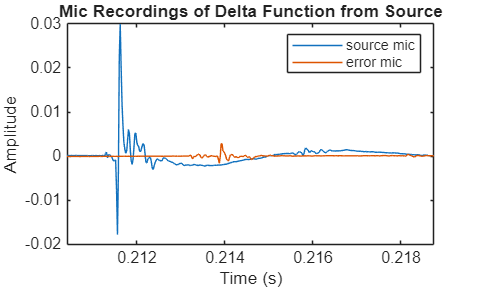

figure
plot(t, mics(:, 2), 'DisplayName', 'source mic')
hold on
plot(t, mics(:, 1), 'DisplayName', 'error mic')
xlim([t(10100), t(10500)]);

legend()
xlabel('Time (s)')
ylabel('Amplitude')
title('Mic Recordings of Delta Function from Source')